close all;
clear variables;
% У себя создал отдельные файлы Exel, чтобы было легче импортировать
a = importdata("30см_Второе_измерение.xlsx");
b = importdata("30см_Третье_измерение.xlsx");
c = importdata("30cm_Первое_измерение.xlsx")

c = struct with fields:
          data: [8×6 double]
      textdata: {2×6 cell}
    colheaders: {'Первое измерение'  'Амплитуда'  'Период'  'Амплитуда в радианах'  'Логарифм от амплитуды в градусах'  'Амплитуда в квадрате'}


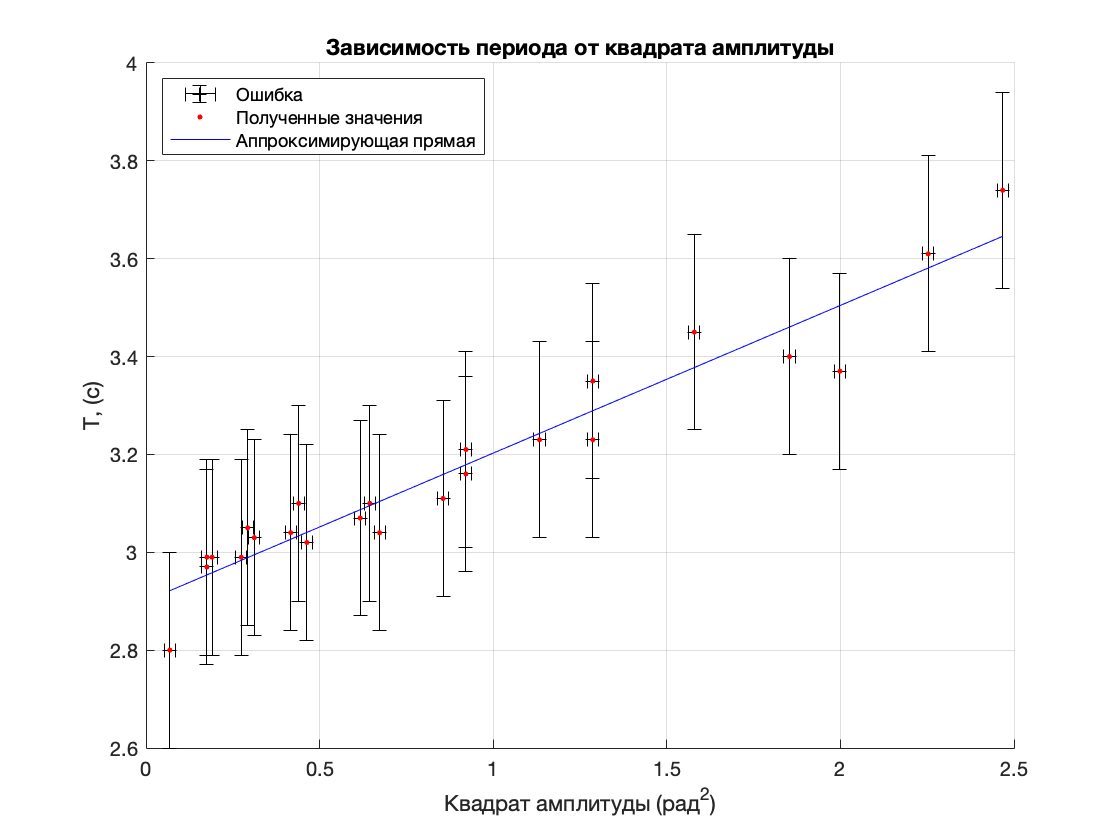

y = [a.data(:,3)', b.data(:,3)', c.data(:,3)'];
x = [a.data(:,5)', b.data(:,6)', c.data(:,6)'];
xpos = 0.016 * ones(1,24);
xneg = xpos;
ypos = 0.2 * ones(1,24);
yneg = ypos;
f1 = figure();
hold all;
grid on;

xlabel('Квадрат амплитуды (рад^2)');
ylabel('T, (с)')
errorbar(x,y,yneg,ypos,xneg,xpos,'k+');

plot(x,y,"r.");
appr = polyfit(x,y,1);
y1 = polyval(appr, x);
plot(x,y1,'b');
legend( 'Ошибка','Полученные значения', 'Аппроксимирующая прямая','Location',"northwest");
title('Зависимость периода от квадрата амплитуды');
saveas(f1,'2Labaa1_4_3_T_A.png');

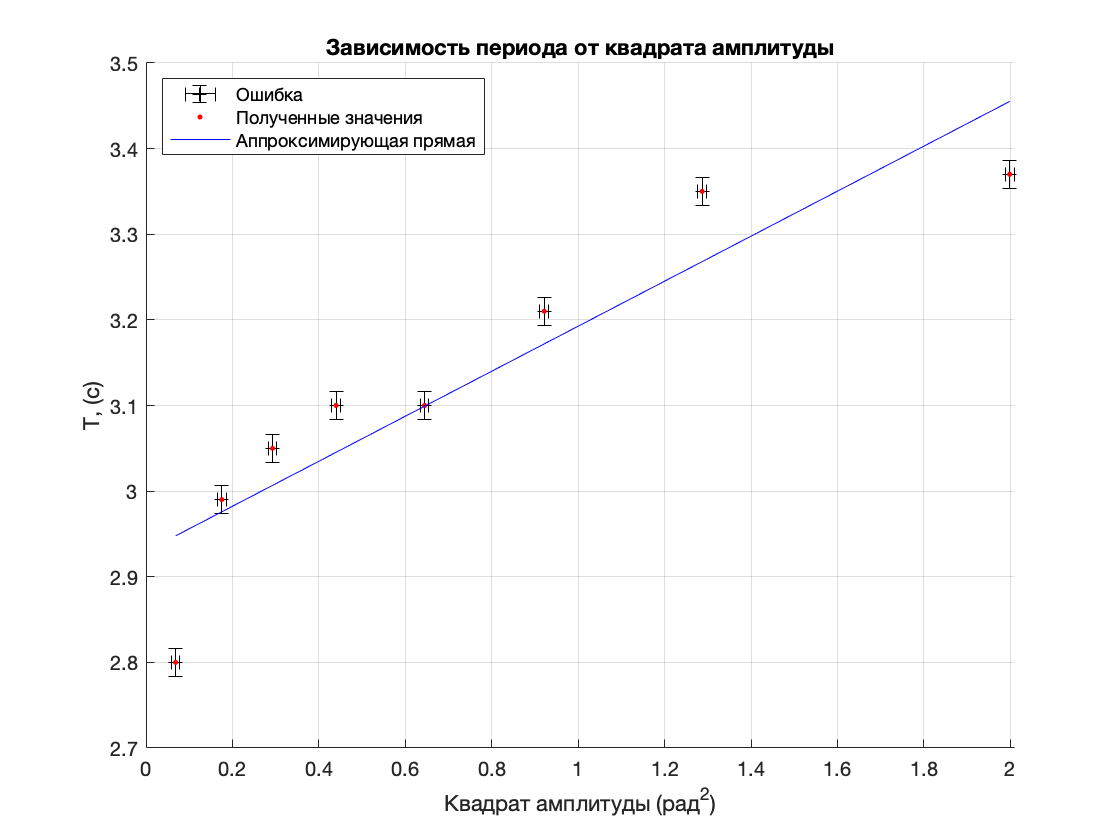

a = importdata("30см_Третье_измерение.xlsx");
y = a.data(:,3);
x = a.data(:,6);
xpos = 0.016 * ones(1,8);
xneg = xpos;
ypos = 0.01 * ones(1,8);
yneg = ypos;
f2 = figure();
hold all;
grid on;

xlabel('Квадрат амплитуды (рад^2)');
ylabel('T, (с)')
errorbar(x,y,xneg,xpos,yneg,ypos,'k+');

plot(x,y,"r.");
appr = polyfit(x,y,1);
y1 = polyval(appr, x);
plot(x,y1,'b');
legend( 'Ошибка','Полученные значения', 'Аппроксимирующая прямая','Location',"northwest");
title('Зависимость периода от квадрата амплитуды');
saveas(f2,'3Labaa1_4_3_T_A.png');